# Laboratory 9

## Exercise 0

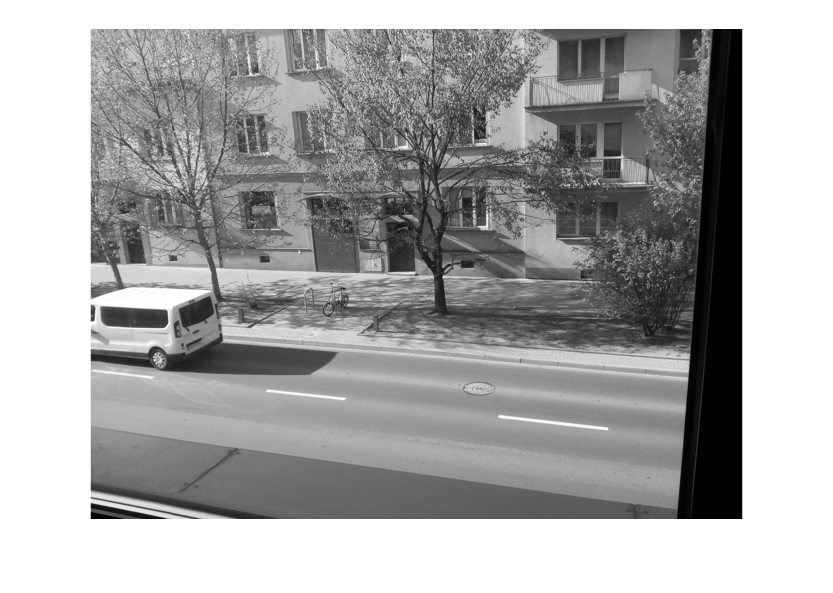

tab4 = importdata("tab_4.mat");
imshow(tab4);

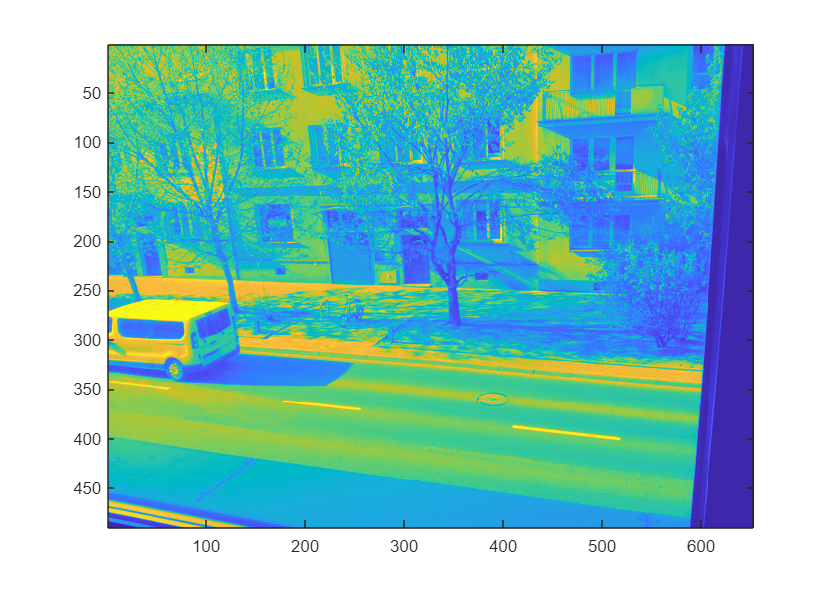

imagesc(tab4);

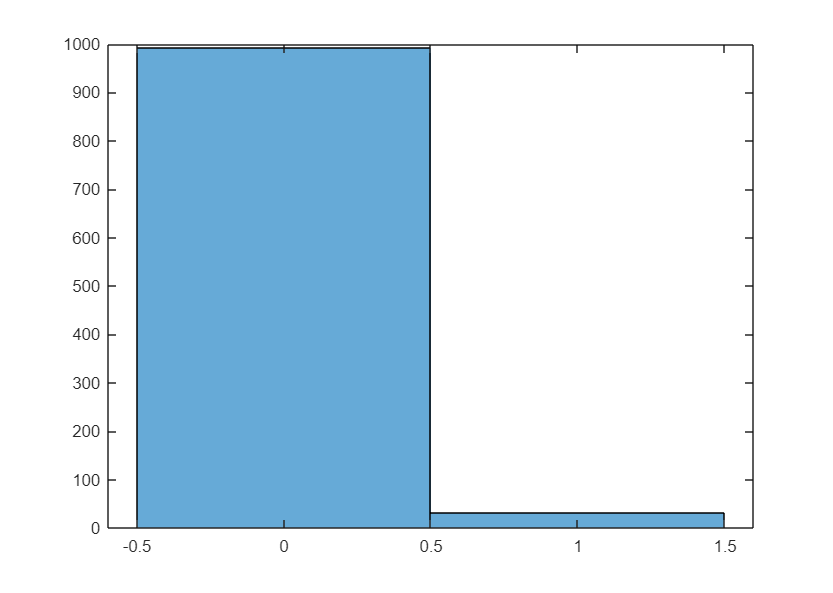

I = eye(32);
histogram(I)

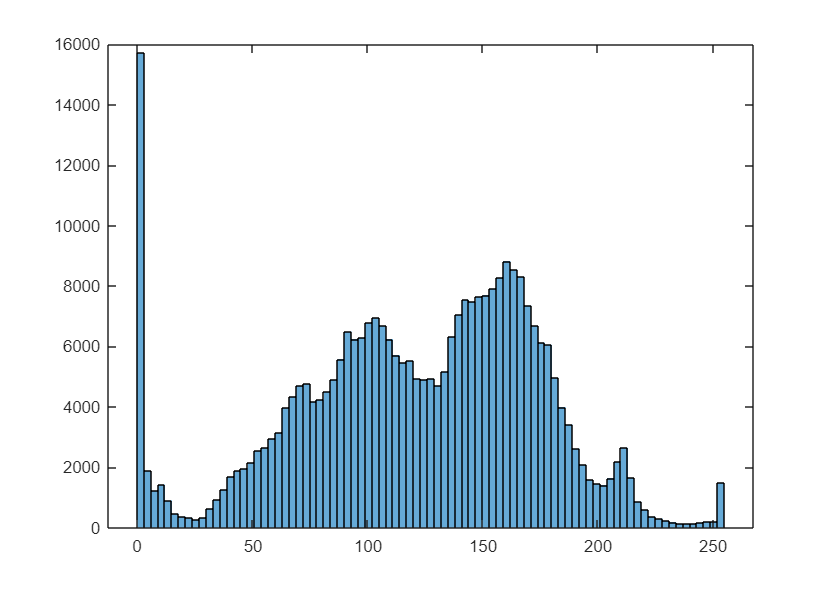

histogram(tab4)

## Exercise 1

tab4_mean = mean(tab4)

tab4_mean =   141.3163  140.6286  140.8653  142.2347  148.6102  148.2612  146.5143  148.1776  150.2633  148.7857  147.5755  146.6429  145.9306  146.5429  146.5633  145.9571  145.6490  144.3592  143.8980  143.2490  143.2306  143.0184  143.4041  143.3490  143.1673  142.6490  142.5531  143.1286  142.6306  142.6980  145.7918  146.9082  147.0592  147.0490  146.1245  146.0265  145.7469  145.6898  145.2429  144.5592  144.2245  144.4592  144.6633  143.7755  144.1102  144.6551  145.9694  144.7959  145.1531  145.2020


tab4_totatmean = mean(tab4, 'all')

tab4_totatmean = 120.2999

tab4_std = std(double(tab4))

tab4_std =    47.6879   48.5808   48.9055   48.1426   49.2023   49.6135   49.6761   49.0572   48.0613   46.3129   46.8741   46.7429   47.0255   47.6048   47.2608   47.4222   47.6182   48.2732   48.4803   48.7212   48.8948   49.2427   48.7389   48.3224   48.1104   47.7446   47.6193   47.8763   47.7921   48.2155   48.6778   50.2703   50.4270   49.8959   50.0182   50.4860   51.4173   52.5746   53.9139   53.7085   53.6245   53.9282   54.0892   54.7243   54.8388   54.3688   53.9019   53.2794   52.8918   52.3822


A = [1 2 3;4 5 6];
A(:);
find(A==3);
find(A(:)==3);
ind = find(A==3);
[rows_ind columns_ind] = find(A==3);
[rows_ind_a columns_ind_a] = find(A(:)==3);
A(rows_ind(1), columns_ind(1));
A(ind(1));
%A(rows_ind_a(1), columns_ind_a(1)) % error. Why?
size(A); % this is why. row index > rows in matrix
found_indeices = find(tab4 < 2*tab4_mean)

found_indeices =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


tab4(found_indeices)

ans = 315840×1 uint8 column vector
   195
   181
   157
   167
   169
   176
   181
   182
   219
   190


reset_tab4 = tab4;
reset_tab4(found_indeices) = 0

reset_tab4 = 490×653 uint8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

## Exercise 2

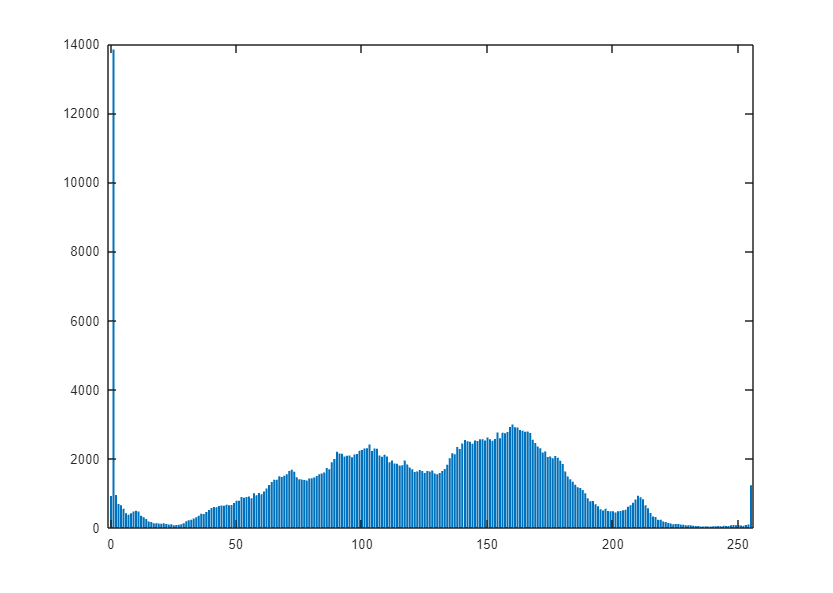

tab4;
[unique_elements, unique_index, tab_index] = unique(tab4);
element_count = zeros(size(unique_elements));
for k = 1:size(element_count)
    element_count(k) = size(find(tab4 == unique_elements(k)),1);
end
bar(unique_elements, element_count)

histogram(tab4)

## Exercise 3

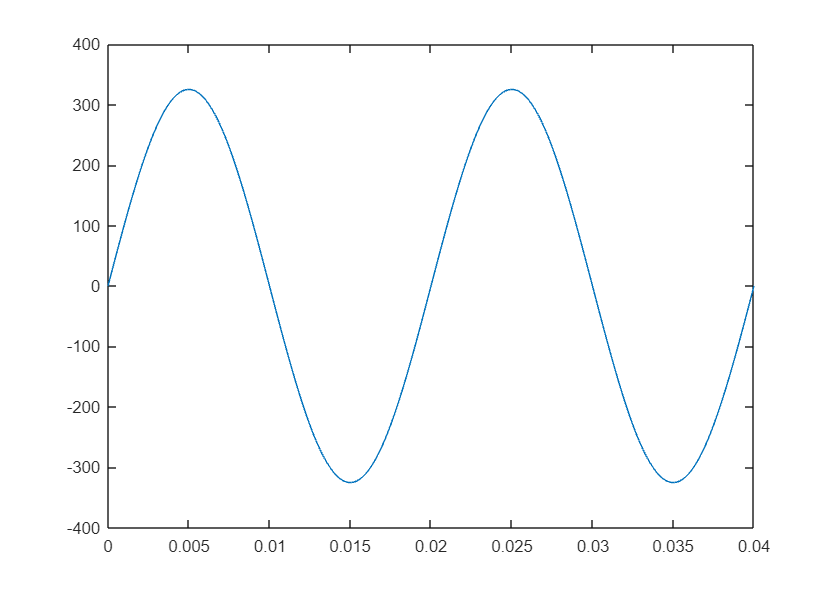

amplitude = 325;
frequency = 50;
dt = 0.0001;
t = 0:dt:0.04;
x = amplitude * sin(2*pi*frequency*t);
plot(t, x);

points = find(abs(x-300) < 5)

points =     38    39    63    64   238   239   263   264


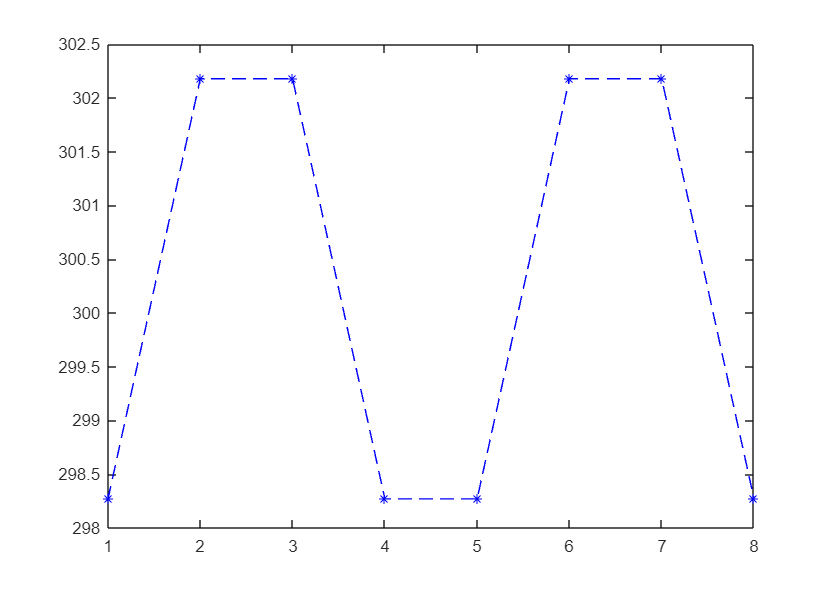

plot(x(points), '--*b')

### Exercise 3b

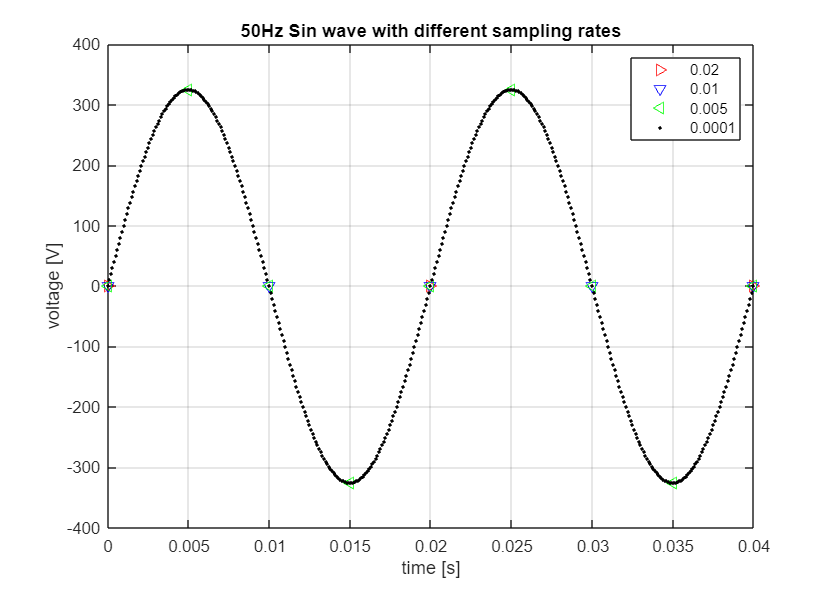

amplitude = 325;
frequency = 50;
dt = [0.02, 0.01, 0.005, 0.0001];
ta = 0:dt(1):0.04;
tb = 0:dt(2):0.04; 
tc = 0:dt(3):0.04;
td = 0:dt(4):0.04;
xa = amplitude * sin(2*pi*frequency*ta);
xb = amplitude * sin(2*pi*frequency*tb);
xc = amplitude * sin(2*pi*frequency*tc);
xd = amplitude * sin(2*pi*frequency*td);
plot(ta, xa, '>r'); hold on;
plot(tb, xb, 'vb');
plot(tc, xc, '<g');
plot(td, xd, '.k');
title('50Hz Sin wave with different sampling rates')
legend('0.02', '0.01', '0.005', '0.0001')
xlabel('time [s]')
ylabel('voltage [V]')
grid on